## Read data


datdir = '/Users/clinpsywoo/Dropbox/2011-yr/Teaching/R_stats/Stats2_2021Fall/data/study1/';

dat = importdata(fullfile(datdir, 'demographics_anova.csv'));


size(dat.data)

ans =     33    19


33 x 19 에서 33은 subject 명수, 19는 첫번째 열은 age, 2-10열까지 rating_low_down, rating_low_passive, rating_low_up, rating_med_down... 순서. 11-19열까지 nps_...

rating = dat.data(:,2:10);
nps = dat.data(:,11:19);

for i = 1:33
%     x{i} = [-1 -1 -1 0 0 0 1 1 1;-1 0 1 -1 0 1 -1 0 1]';
    x{i} = [1 1 1 2 2 2 3 3 3;1 2 3 1 2 3 1 2 3]';
    x{i} = [1 1 1 3 3 3 5 5 5;1 2 3 1 2 3 1 2 3]';
    x{i}(:,3) = zscore(x{i}(:,1)).*zscore(x{i}(:,2));
    y_rating{i} = rating(i,:)';
    y_nps{i} = nps(i,:)';
end


## Multi-level GLM

x: heat intensity & regulation

y: ratings or nps

% run the multilevel GLM
stats = glmfit_multilevel(y_rating, x, [], 'names', {'intercept', 'heat_level', 'regulation', 'interaction'});

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  33, Predictors:   1
Outcome names: intercept	heat_level	regulation	interaction	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.00 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	intercept	heat_level	regulation	interaction	
Adj. mean	4.71	20.18	12.44	-1.86	

2nd-level B01
	intercept	heat_level	regulation	interaction	
Coeff	4.71	20.18	12.44	-1.86	
STE	8.58	1.25	2.87	1.44	
t	0.55	16.15	4.33	-1.30	
Z	0.54	8.21	3.81	-1.27	
p	0.58720	0.00000	0.00014	0.20409	

________________________________________


% with weighted option
stats = glmfit_multilevel(y_rating, x, [], 'names', {'intercept', 'heat_level', 'regulation', 'interaction'}, 'weighted');

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  33, Predictors:   1
Outcome names: intercept	heat_level	regulation	interaction	
Weighting option: weighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	R & B - type Empirical Bayes reweighting.
Total time: 0.00 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	intercept	heat_level	regulation	interaction	
Adj. mean	-12.80	38.82	12.36	-1.13	

2nd-level B01
	intercept	heat_level	regulation	interaction	
Coeff	-12.80	38.82	12.36	-1.13	
STE	9.34	2.51	2.73	1.31	
t	-1.37	15.47	4.53	-0.87	
Z	-1.34	8.21	3.94	-0.85	
p	0.18038	0.00000	0.00008	0.39378	

________________________________________


% with weighted option + bootstrap option
stats = glmfit_multilevel(y_rating, x, [], 'names', {'intercept', 'heat_level', 'regulation', 'interaction'}, 'weighted', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  33, Predictors:   1
Outcome names: intercept	heat_level	regulation	interaction	
Weighting option: weighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	R & B - type Empirical Bayes reweighting.
 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.41 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intercept	heat_level	regulation	interaction	
Adj. mean	-12.98	38.84	12.40	-1.14	

2nd-level B01
	intercept	heat_level	regulation	interaction	
Coeff	-12.80	38.82	12.36	-1.13	
STE	9.07	2.27	2.55	1.23	
t	-1.37	15.47	4.53	-0.87	
Z	-1.50	3.80	3.88	-0.83	
p	0.13461	0.00014	0.00011	0.40610	

________________________________________


Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  33, Predictors:   1
Outcome names: intercept	heat_level	regulation	interaction	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: Yes
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.00 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	intercept	heat_level	regulation	interaction	
Adj. mean	-15.48	40.37	12.44	-1.86	

2nd-level B01
	intercept	heat_level	regulation	interaction	
Coeff	-15.48	40.37	12.44	-1.86	
STE	9.25	2.50	2.87	1.44	
t	-1.67	16.15	4.33	-1.30	
Z	-1.62	8.21	3.81	-1.27	
p	0.10417	0.00000	0.00014	0.20409	

________________________________________
Warning! Unknown input string option.


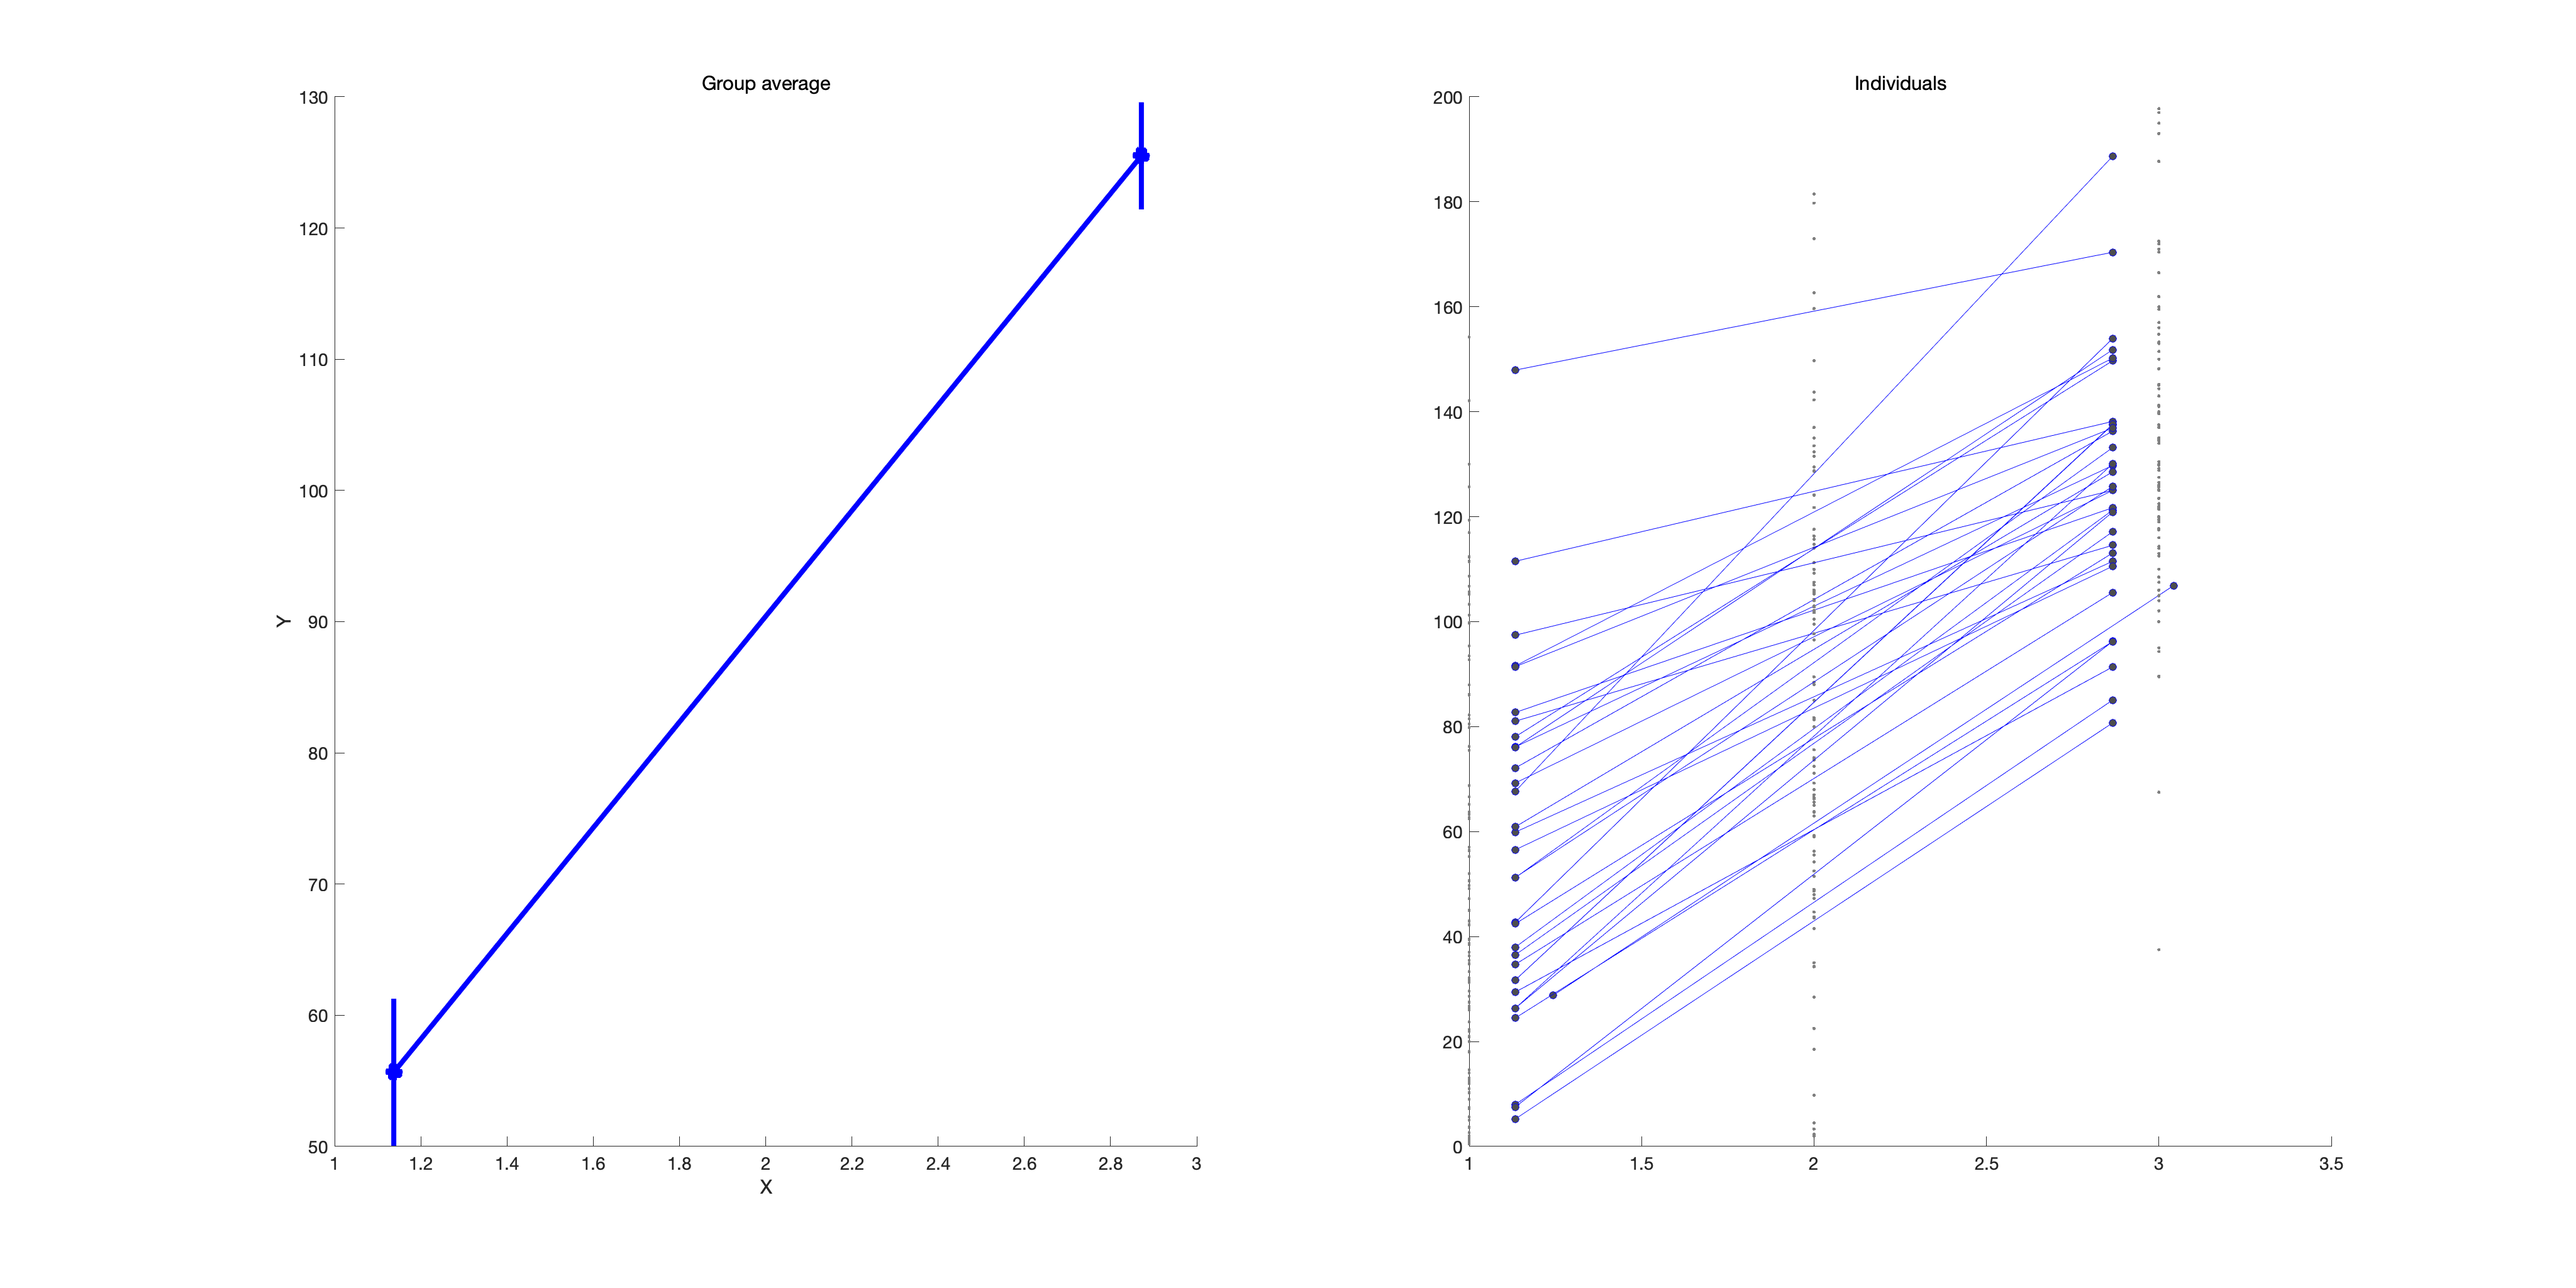

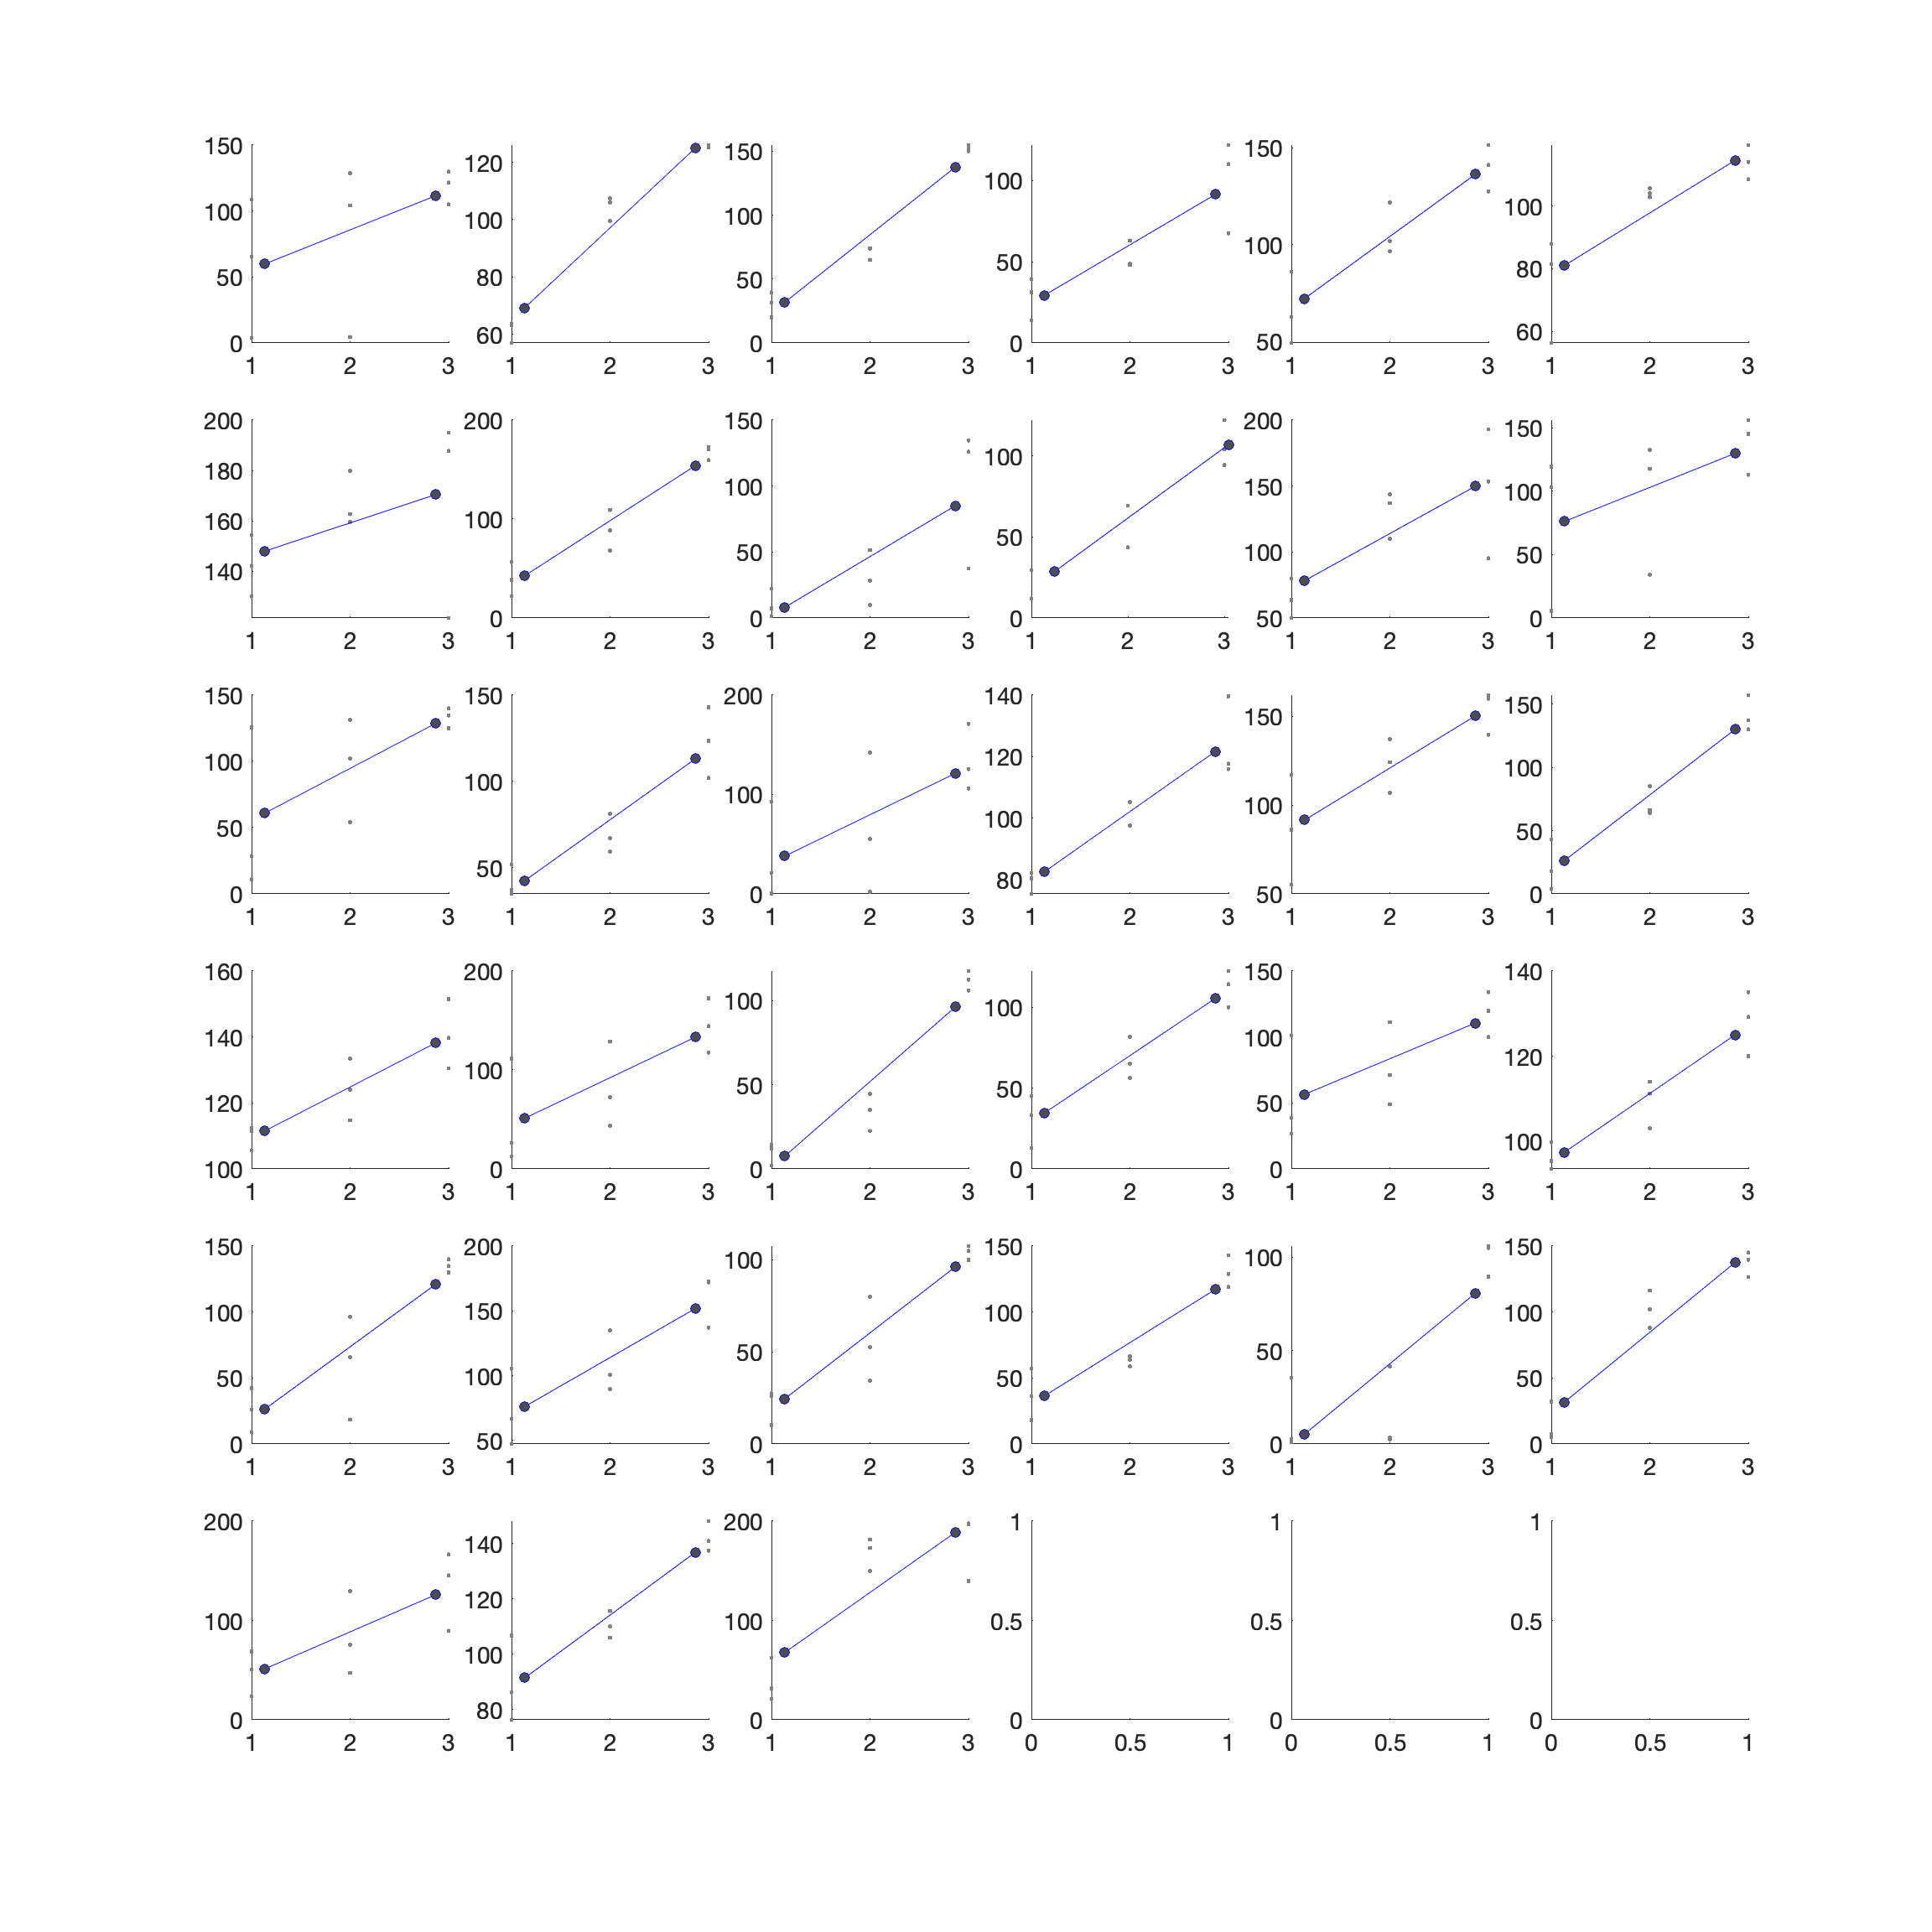

% with plot option
stats = glmfit_multilevel(y_rating, x, [], 'names', {'intercept', 'heat_level', 'regulation', 'interaction'}, 'plot');

% for nps
stats = glmfit_multilevel(y_nps, x, [], 'names', {'intercept', 'heat_level', 'regulation', 'interaction'});  

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  33, Predictors:   1
Outcome names: intercept	heat_level	regulation	interaction	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.00 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	intercept	heat_level	regulation	interaction	
Adj. mean	-3.28	4.63	0.03	-0.05	

2nd-level B01
	intercept	heat_level	regulation	interaction	
Coeff	-3.28	4.63	0.03	-0.05	
STE	1.17	0.53	0.39	0.39	
t	-2.80	8.68	0.07	-0.13	
Z	-2.62	6.18	0.07	-0.13	
p	0.00870	0.00000	0.94265	0.89838	

________________________________________


## Mediation analysis

x1: temperature

x2: regulation

m: nps

y: rating

for i = 1:33
    x1{i} = [1 1 1 2 2 2 3 3 3]';
    x2{i} = [1 2 3 1 2 3 1 2 3]';
    m{i} = nps(i,:)';
    y{i} = rating(i,:)';
end

[paths, stats] = mediation(x1, y, m, 'verbose');

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.

________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	4.32	0.63	35.13	39.07	2.00	
STE	0.50	0.39	3.15	2.67	1.50	
t (~N)	8.60	1.61	11.16	14.61	1.33	
Z	6.12	1.56	6.90	7.92	1.30	
dfe	31.40	25.84	29.00	30.60	24.66	
p	0.0000	0.1196	0.0000	0.0000	0.1948	

________________________________________
Total time:   0 s


[paths, stats] = mediation(x2, y, m, 'verbose');

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.

________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	0.12	4.41	13.19	12.34	-0.24	
STE	0.41	0.57	2.72	2.52	1.57	
t (~N)	0.29	7.75	4.85	4.90	-0.16	
Z	0.29	5.63	4.13	4.17	-0.15	
dfe	28.67	28.34	29.69	29.97	28.54	
p	0.7742	0.0000	0.0000	0.0000	0.8778	

________________________________________
Total time:   0 s


[paths, stats] = mediation(x1, y, m, 'verbose', 'bootsamples', 10000);

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.

________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	4.32	0.63	35.13	39.07	2.00	
STE	0.50	0.39	3.15	2.67	1.50	
t (~N)	8.60	1.61	11.16	14.61	1.33	
Z	6.12	1.56	6.90	7.92	1.30	
dfe	31.40	25.84	29.00	30.60	24.66	
p	0.0000	0.1196	0.0000	0.0000	0.1948	

________________________________________
Total time:   0 s


Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.
geom2d toolbox on your path.  I can't find it, so the path diagram will be skipped.


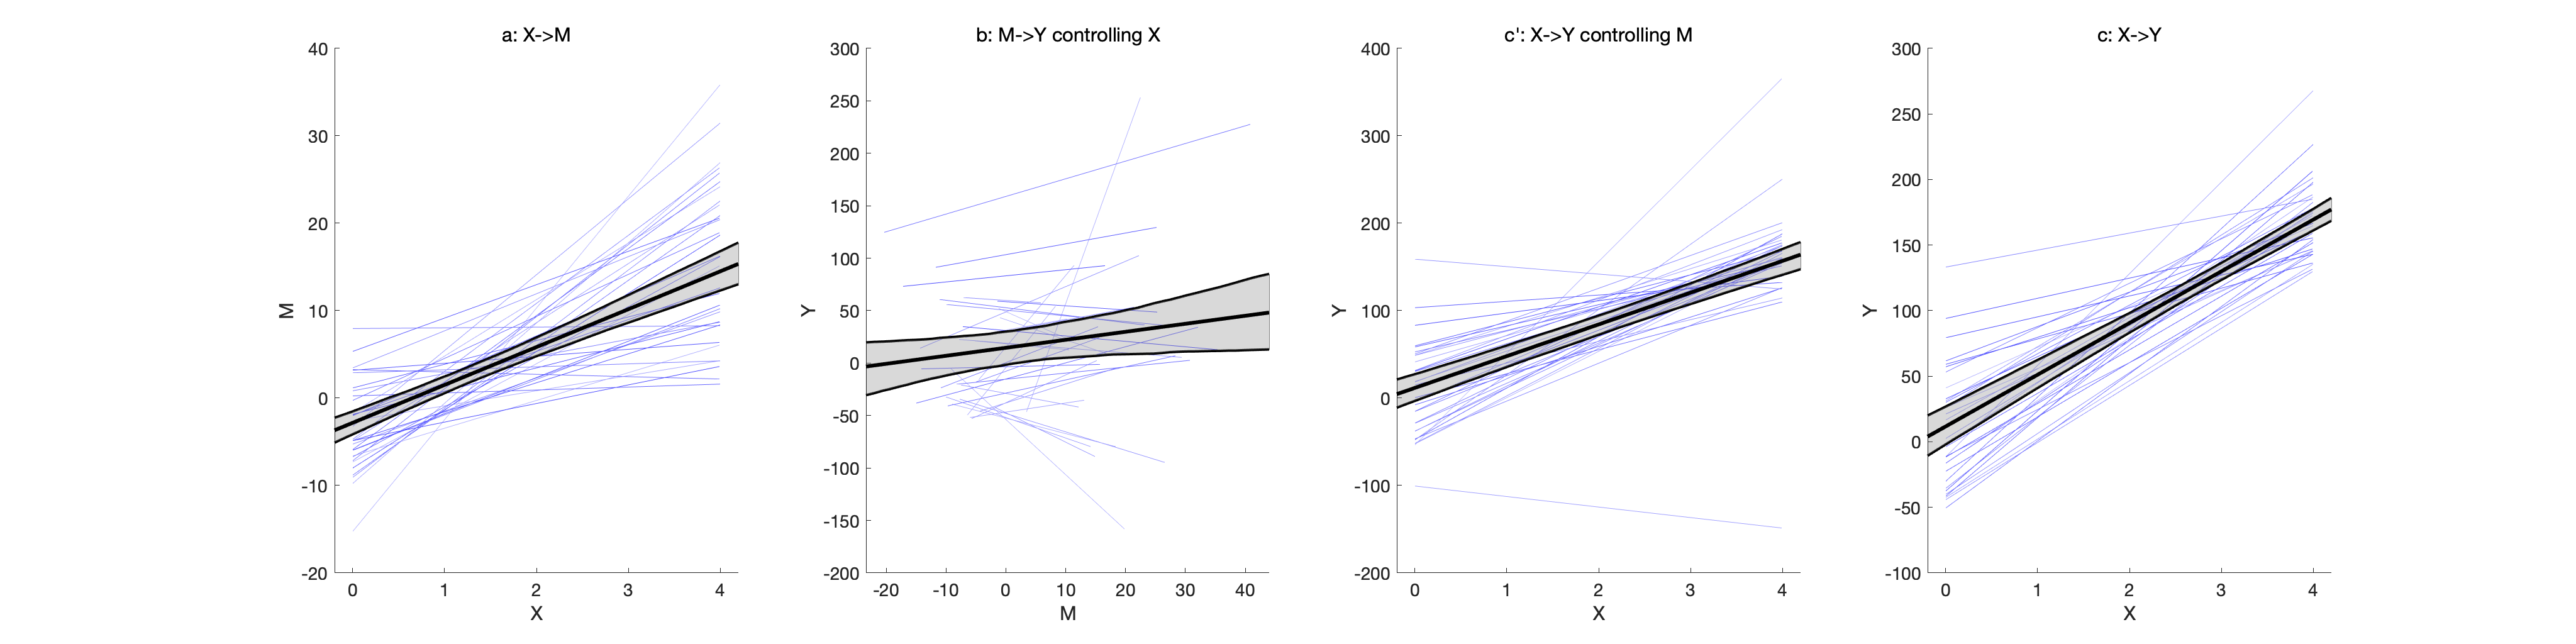

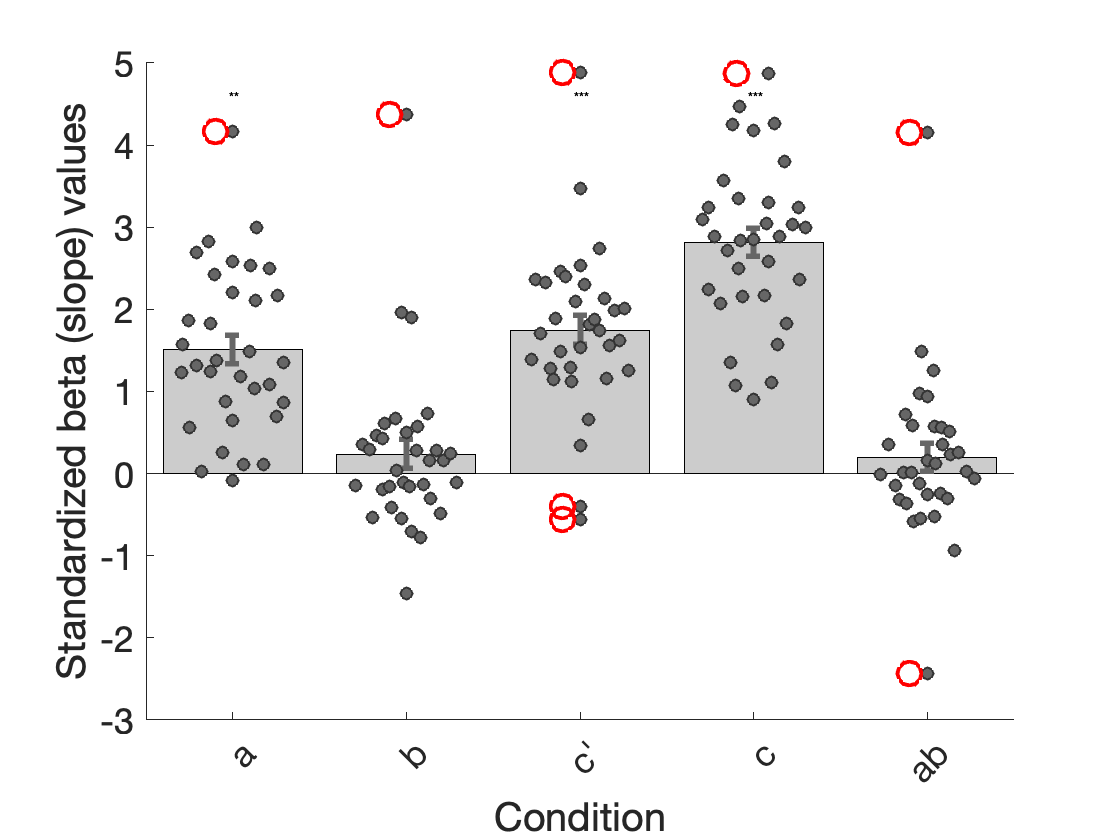

No second-level covariates; omitting 2nd level scatterplots.
Cannot find ebayes_bstar field in stats output, so cannot create cov(a,b) scatterplot

________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	4.32	0.63	35.13	39.07	2.00	
STE	0.50	0.39	3.15	2.67	1.50	
t (~N)	8.60	1.61	11.16	14.61	1.33	
Z	6.12	1.56	6.90	7.92	1.30	
dfe	31.40	25.84	29.00	30.60	24.66	
p	0.0000	0.1196	0.0000	0.0000	0.1948	

________________________________________
Total time:   4 s


[paths, stats] = mediation(x1, y, m, 'verbose', 'plots','bootsamples', 10000);